## 1. Ecuacion diferencial ordinaria de primer orden

Usando el método RK4, resuelve el siguiente problema de valor inicial en el intervalo de t=0 a t=2, donde y(0)=1.

Grafica la solución $y\left(t\right)\ldotp$


$$\frac{\mathrm{d}}{\mathrm{d}t}y\left(t\right)=y{\left(t\right)t}^2 -1\ldotp 1y\left(t\right)$$


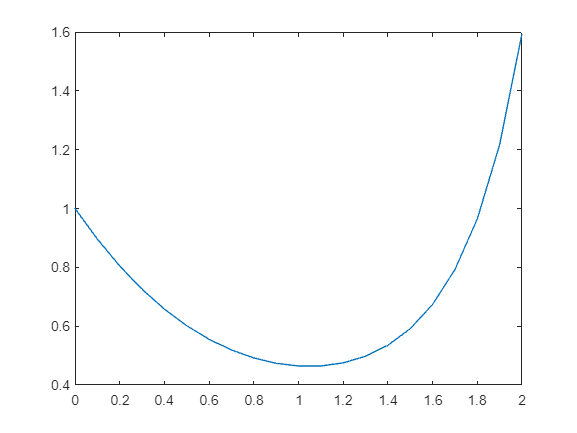

%Valores iniciales
t0=0; tf=2; y0=1; h=0.1;
f=@(t,y) y*t^2-1.1*y;
[t1,y1]=TerPar_RK4(f,t0,y0,h,tf);
plot(t1,y1)

## 2. Sistema de dos ecuaciones de primer orden - Métodos de paso variable.

Usando RKF45, resuelve el siguiente sistema en el rango de t=0 a t=0.4, con y(0)=2 y z(0)=4. Grafica la solución $y\left(t\right)\;\&\;z\left(t\right)\ldotp$


$$\frac{\mathrm{d}}{\mathrm{d}t}y\left(t\right)=-2y\left(t\right)+5e^{-t}$$



$$\frac{\mathrm{d}}{\mathrm{d}t}z\left(t\right)=-\frac{y\left(t\right){*z}^2 \left(t\right)}{2}$$


Usa h=0.1 e imprime el número total de puntos calculados por este método de paso variable. 

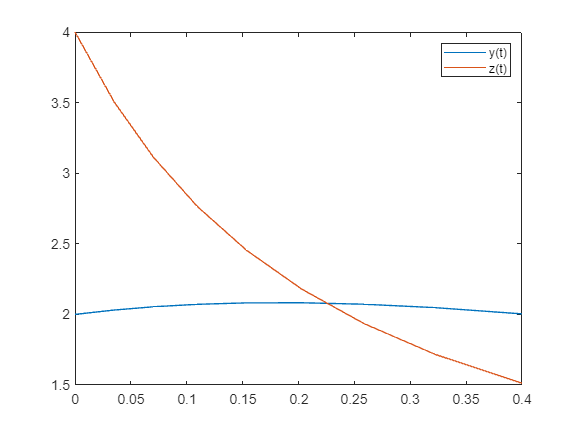

%Valores iniciales
t0=0;tf=0.4;y0=[2;4];h=0.1;
f = @(t,y) [-2*y(1)+5*exp(-t);-(y(1)*y(2)^2)/2];
[t2,y2]=TerPar_odeRFK45MV(f,y0,t0,tf,h,10^(-6),1000);
plot(t2,y2)
legend('y(t)','z(t)')

## 3. Ecuación diferencial ordinaria de segundo orden - Métodos de múltiples pasos

Usando el método ABM4o, igual al ABM4 pero que solo guarda los últimos 4 valores de la función, resuelve el siguiente problema de t=0 a t=5.


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y\left(t\right)+0\ldotp 6\frac{\mathrm{d}}{\mathrm{d}t}y\left(t\right)+8y\left(t\right)=0$$


donde y(0)=4 y y'(0). Grafica la solución y(t).

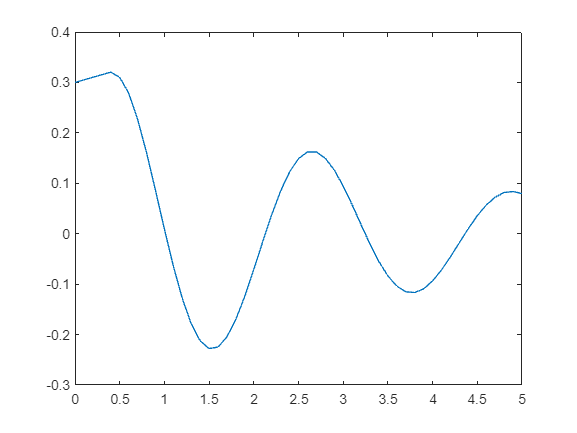

t0=0;tf=5;y0=[4;0];h=0.1;
f=@(t,y)[y(2); -(0.6*y(2)+8*y(1))];
[t3,y3]=TerPar_AMB4o(f,y0,t0,tf,h);
plot(t3,y3(1,:))

### RK4

function [t,y] = TerPar_RK4(f,t0,y0,h,tf)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:(n-1)
        k1=f(t(i),y(:,i));
        k2=f(t(i)+(1/2)*h,y(:,i)+(1/2)*k1*h);
        k3=f(t(i)+(1/2)*h,y(:,i)+(1/2)*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end

### RKF45

function [t,y] = TerPar_odeRFK45MV(f,y0,t0,tf,h,relTol,max)
    i=1;
    t(i)=t0;
    y(:,i)=y0;
    while t(end)<tf && i<max
        if t(end)+1.1*h >= tf
            h=tf-t(end);
        end
        w = y(:,end);
        s1=f(t(end),w);
        s2=f(t(end)+1/4*h,w+1/4*h*s1);
        s3=f(t(end)+3/8*h,w+3/32*h*s1+9/32*h*s2);
        s4=f(t(end)+12/13*h, w+1932/2197*h*s1 -7200/2197*h*s2 + 7296/2197*h*s3);
        s5=f(t(end)+h,w + 439/216*h*s1 -8*h*s2 +3680/513*h*s3 -845/4104*h*s4);
        s6=f(t(end)+1/2*h, w-8/27*h*s1+2*h*s2-3544/2565*h*s3 +1859/4104*h*s4 -11/40*h*s5);
        wp=w;
        w=wp+h*(25/216*s1 + 1408/2565*s3 + 2197/4104*s4 - 1/5*s5);
        z=wp+h*(16/135*s1 +6656/12825*s3 + 28561/56430*s4 - 9/50*s5 +2/55*s6);
        re=norm((z-w)./z, Inf);
        if re <= relTol
            t(end+1) = t(end)+h;
            y(:,end+1) = z;
            i=i+1;
        end
        h= 0.9*h*nthroot(relTol/re,5); % nthroot saca la raíz quinta (5)
    end
end

### ABM4o

function [t,y]=TerPar_AMB4o(f,y0,t0,tf,h)
    steps=4; 
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0) ,n);
    fv=zeros(length(y0),steps);
    [t(1:steps),y(:,1:steps)]=TerPar_RK4(f,t0,t0+h*(steps-1),y0,h);
    fv(:,1:steps)=bsxfun(f,t(1:steps),y(:,1:steps)); %agarra un valor de la t, y la primer columna del y y aplica la funcion f.
    for i=4:n-1
        %predictor-Adams-Bashford
        y(:,i+1)= y(:,i) + (h/24)*( 55*fv(:,steps) - 59*fv(:,steps-1) + 37*fv(:,steps-2) - 9*fv(:,steps-3));
        fv(:,1:steps-1) = fv(:,2:steps);
        fv(:,steps)=f(t(i+1),y(:,i+1));
        %corrector
        y(:,i+1)=y(:,i) + (h/24)*( 9*fv(:,steps) + 19*fv(:,steps-1) - 5*fv(:,steps-2) + fv(:,steps-3));
        fv(:,steps)=f(t(i+1),y(:,i+1));
    end
end